# First basic plot

% Data for plot 1
y = linspace(1000,200,6);
x = linspace(10,22,6);

% Create plot - give a plot handle
p1 = plot(x,y);


## Add elements

% Add color
p1.Color = 'r';
% Change linewidth
p1.LineWidth = 3

## Add second data set

y2 = linspace(1000,100,6);
hold on
p2 = plot(x,y2);

## Add elements to second plot

% Change Marker, Color, LineWidth and LineStyle
p2.Color = [0 0 1]
p2.LineWidth = 3
p2.LineStyle = ':'

## Add Axis limits

xlim([8 24])
ylim([0 1200])
set(gca,'XLim',[8 24])

## Add Axis labels

ylabel('Intensity (lux)')
xlabel('Distance (cm)')

## Title

title('Light intensity as a function of distance')

## Legend

legend([p1,p2],'Theory','Experiment')

## Text on plot

text(9,100,'Comparison between theory and experiment')

## Minor axis ticks

% Create handle for 'gca' - 'get current axis' which handles all properties
h = gca;
h.XAxis.MinorTick = 'on';
h.XAxis.MinorTickValues = [9,11,13,15,17,19,21,23];



## Figure properties Part II

close all
f = figure(1);
plot(1:10,1:10)
% Get and set
get(f)

f.Color = [1 1 0.5];

f.Name = 'My Data Figure';

% Give handles to more than one figure
close all
f1=figure(1);
plot(1:10,1:10)
f2=figure(2);
plot(1:10,1:10)
f1.Color = [1 1 .5];
f2.Color = [1 0.5 0];

% Change set values in for loop
clear
close all
clist=[1 0 0; 0.5 1 1]; % 2 RGB Vectors
for i = 1:2
    f(i) = figure(i);
    plot(1:10,1:10)
    f(i).Color = clist(i, :);
end


## Subplots

figure(1)
subplot(2,2,1) % Number of rows , Number of columns , identify of current subplot
plot(1:10,1:10)
subplot(2,2,4)
plot(1:10,1:10)

close all
figure(1)
subplot(2,2,1:2)
plot(1:10,1:10)
subplot(2,2,3)
plot(1:10,1:10)
subplot(2,2,4)
plot(1:10,1:10)


## Axes, Ticks and Labels

% Title and label
a1 = subplot(1,2,1);
title(a1,'Plot 1');
xlabel(a1,'my x axis');
ylabel(a1,'my y axis');

a2 = subplot(1,2,2)
title(a2,'Plot 2');
xlabel(a2,'your x axis');
ylabel(a2,'your y axis');

% Tick mark spread
set(a2, 'XTick', 0:1:3);
set(a2, 'YTick', [1 100 1000]);


% Use . dot notation to change X and Y tick for a1
a2.XTick = [0.1 0.3 0.4 0.6]
a1.YTick = [0.2 0.7]

% Tick mark label
set(a2, 'XTickLabel',{'Zero','One','Two','Three'})
set(a2, 'YTickLabel', [1 1/100 1/1000]);

## PRACTICE

## Set Background Figure Color to Green

f1 = figure(1);
% YOUR CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
f1.Color = 'g'
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Create Handles for two subplots (1 row , 2 columns, 2 plots); use a1 and a2

% YOUR CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% subplot 1
a1 = subplot(1,2,1)

a1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


plot(1:10,1:10)
% subplot 2
a2 = subplot(1,2,2)

a2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


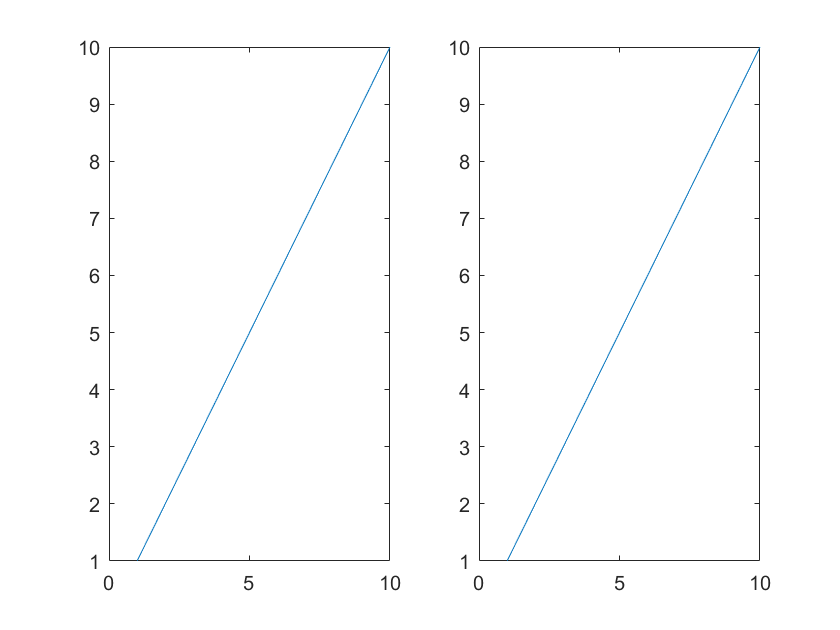

plot(1:10,1:10)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Change background color of subplots, using subplot handles (a1 = blue , a2 = red)

% YOUR CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% subplot 1 (a1)
a1.Color = 'blue'

a1 =   Axes with properties:

             XLim: [0 10]
             YLim: [1 10]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


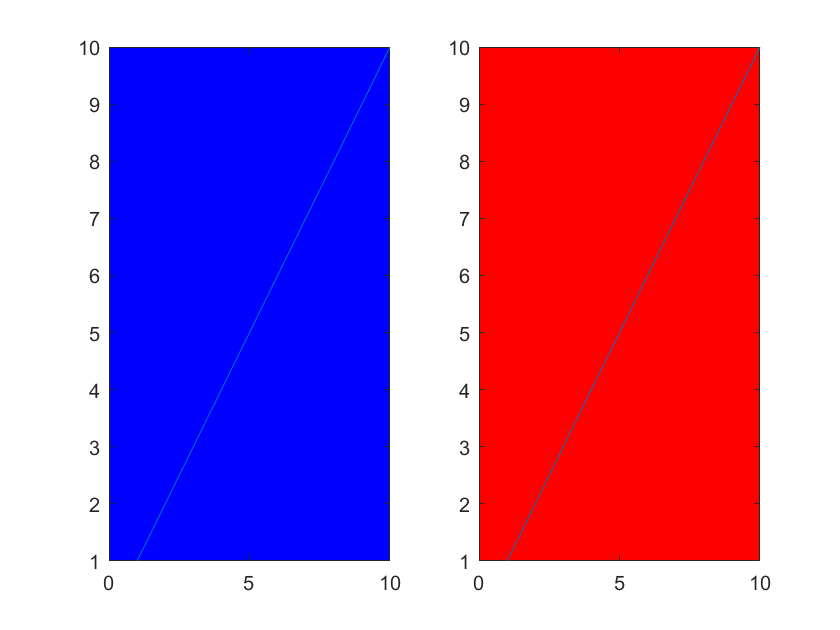

a2 =   Axes with properties:

             XLim: [0 10]
             YLim: [1 10]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


% subplot 2 (a2)
a2.Color = 'red'

## Change Font type, size and weight

% YOUR CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% subplot 1 (a1)
% .FontName (e.g., 'Arial', 'Times New Roman')
a1.FontName = 'Arial';
% .FontSize (e.g., 8, 11, 20)
a1.FontSize = 13

a1 =   Axes with properties:

             XLim: [0 10]
             YLim: [1 10]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


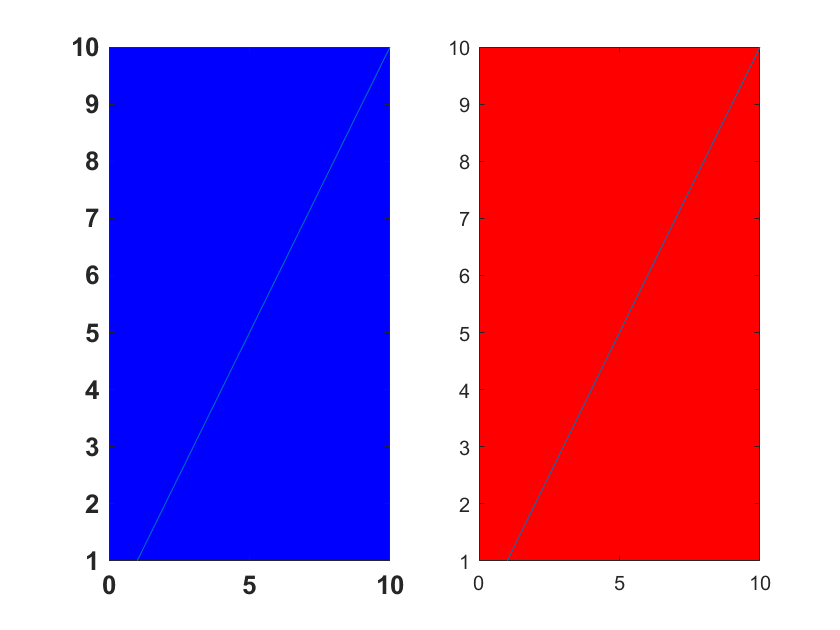

a1 =   Axes with properties:

             XLim: [0 10]
             YLim: [1 10]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


% .FontWeight (e.g., 'bold' or 'normal')
a1.FontWeight = 'bold'

% subplot 2 (a2)
% .FontName (e.g., 'Arial', 'Times New Roman')

% .FontSize (e.g., 8, 11, 20)

% .FontWeight (e.g., 'bold' or 'normal')


## Add Title, Axis Labels - use title and ylabel/xlabel functions

% YOUR CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% subplot 1
% Title
title(a1,'My subplot')
% Y Axis Label
ylabel(a1,'Y measure')
% X Axis Label

% subplot 2
% Title

% Y Axis Label

% X Axis Label



## Change axis limits, ticks, tick labels

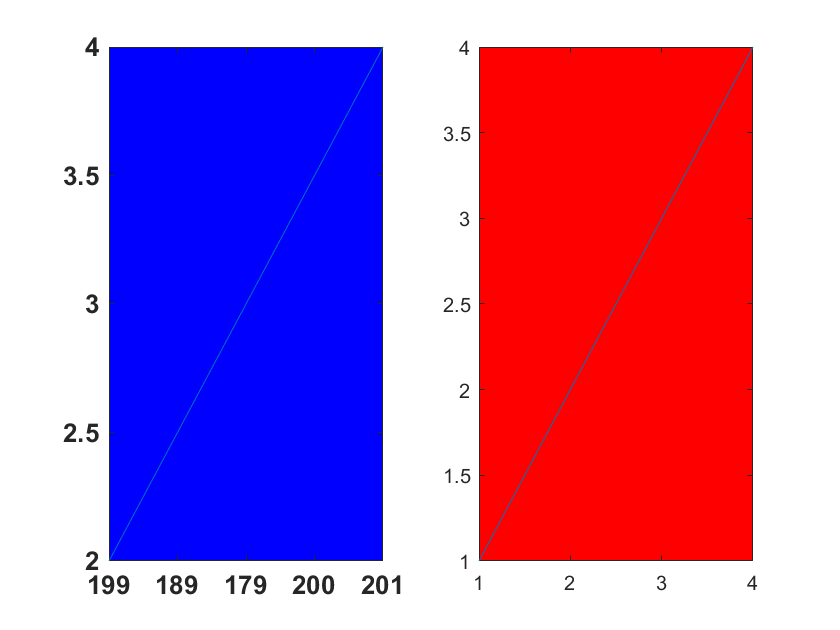

% YOUR CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% subplot 1 
% X Limits
xlim(a1,[2 4])
set(a1,'XLim',[2 4])
% Y Limits
ylim(a2,[1 4])
% X Ticks
xticks(a1,[2 2.5 3 3.5 4])
xticklabels(a1,{'one','two','three','four','five'})

xticklabels(a1,[199 189 179 200 201])


% subplot 2
% X Limits

% Y Limits

% X Ticks


